# Series de Fourier

## Variable compleja

1.- Graficar una expontencial compleja $x\left(t\right)=A\;e^{\mathrm{Bjt}} \;$y visualizarla en 3D

2.- Graficar una expontencial compleja $x\left(t\right)=A\;e^{-\mathrm{Bjt}} \;$y visualizarla en 3D

Basado en las gráficas anteriores: ¿Qué es un *frecuencia negativa*?

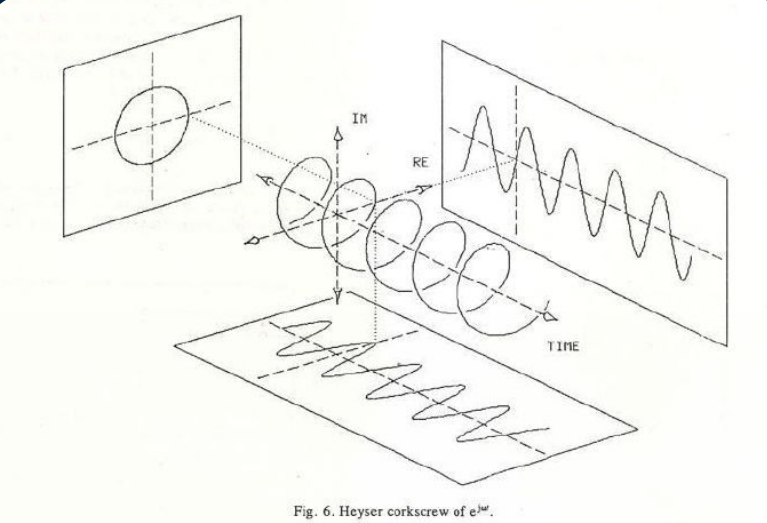

Probar a mano que:

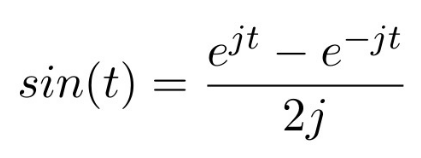

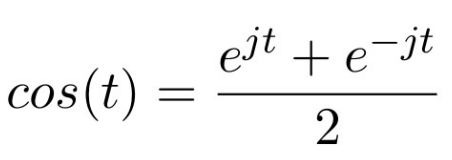

## ¿Por qué $e^{\mathrm{jt}}$?

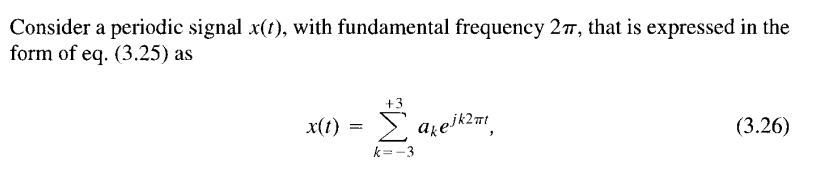

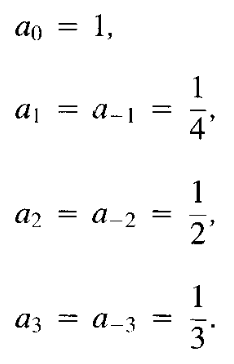

1.- Escribir en código, término por término, esta suma.

2.- Graficar el resultado en 3D

syms t
x = (1/3)*exp(-1i*-3*2*pi*t)+ ...
    (1/2)*exp(-1i*-2*2*pi*t)+ ...
    (1/4)*exp(-1i*-1*2*pi*t)+ ...
    1+ ...
    (1/4)*exp(-1i*1*2*pi*t)+ ...
    (1/2)*exp(-1i*2*2*pi*t)+ ...
    (1/3)*exp(-1i*3*2*pi*t)

$$x = \frac{{\mathrm{e}}^{-2\,\pi \,t\,\mathrm{i}}}{4}+\frac{{\mathrm{e}}^{2\,\pi \,t\,\mathrm{i}}}{4}+\frac{{\mathrm{e}}^{-4\,\pi \,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{4\,\pi \,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{-6\,\pi \,t\,\mathrm{i}}}{3}+\frac{{\mathrm{e}}^{6\,\pi \,t\,\mathrm{i}}}{3}+1$$



figure
fplot3(real(x),t,imag(x))
xlabel("Re")
ylabel("t")
zlabel("Im")



x_2 = (1/4)*exp(-1i*-1*2*pi*t)

$$x\_2 = \frac{{\mathrm{e}}^{2\,\pi \,t\,\mathrm{i}}}{4}$$

x_3 = (1/4)*exp(-1i*1*2*pi*t)

$$x\_3 = \frac{{\mathrm{e}}^{-2\,\pi \,t\,\mathrm{i}}}{4}$$


figure
fplot3(real(x_2),t,imag(x_2))
hold on
fplot3(real(x_3),t,imag(x_3))
xlabel("Re")
ylabel("t")
zlabel("Im")

## Series en forma compleja

1.- Graficar la señal original 

2.- Calcular (con un for) los +/- 5 coeficientes y reconstruir la señal

3.- Calcular (con un for) los +/- 10 coeficientes y reconstruir la señal

(Opcional) Graficar los coeficientes

clear
syms t

x = exp(-t)

$$x = {\mathrm{e}}^{-t}$$

T_intervalo = [0 3];

figure
fplot(x,T_intervalo)

a_k = [];
e_k = [t];

%Un componente
T = 3;
%k = 5

for k = -10:10
    a_k(end+1) = (1/T)*int(x*exp(-1i*k*(2*pi/T)*t),t,T_intervalo);
    e_k(end+1) = exp(1i*k*(2*pi/T)*t);
end

e_k = e_k(2:end);

x_k = sum(a_k.*e_k);

fplot3(real(x_k),t,imag(x_k))
xlabel("Re")
ylabel("t")
zlabel("Im")


%a_5 = (1/T)*int(x*exp(-1i*k*(2*pi/T)*t),t,T_intervalo)

## coeficientes

figure
stem(abs(a_k))

figure
stem(angle(a_k))

## Series en forma coseno fase

Realizar los mismo que el ejercicio anterior, pero ahora para coseno-fase

## Series en forma trigonométrica

You know the drill

## Series de una señal compleja

You know the drill